In the name of God

Ashkan Jafari 810197483

# PreLab #2

## Question1

x=[3 11 7 0 -1 4 2];
h=[2 3 0 -5 2 1];
% convolution
C1 = conv_m(x,h)

C1 =      6    31    47     6   -51    -5    41    18   -22    -3     8     2


C2 = conv(x,h)

C2 =      6    31    47     6   -51    -5    41    18   -22    -3     8     2


## Question3

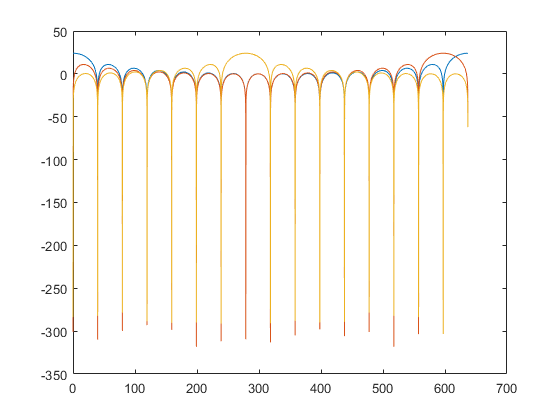

N = 16;
W = zeros(N,N);
for i = 1:N
    for j=1:N
        W(i,j) = exp((-1i*2*pi*(i-1)*(j-1))/N);
    end    
end
Row1=W(1,:);
Row2=W(2,:);
Row10=W(10,:);
num = 256^2;
[h1,w1] = freqz(Row1,1,num,'whole',2001);
[h2,w2] = freqz(Row2,1,num,'whole',2001);
[h10,w10] = freqz(Row10,1,num,'whole',2001);
db1=20*log10(abs(h1));
db2=20*log10(abs(h2));
db10=20*log10(abs(h10));

plot(w1/pi,db1, w2/pi,db2, w10/pi,db10)

## Question4

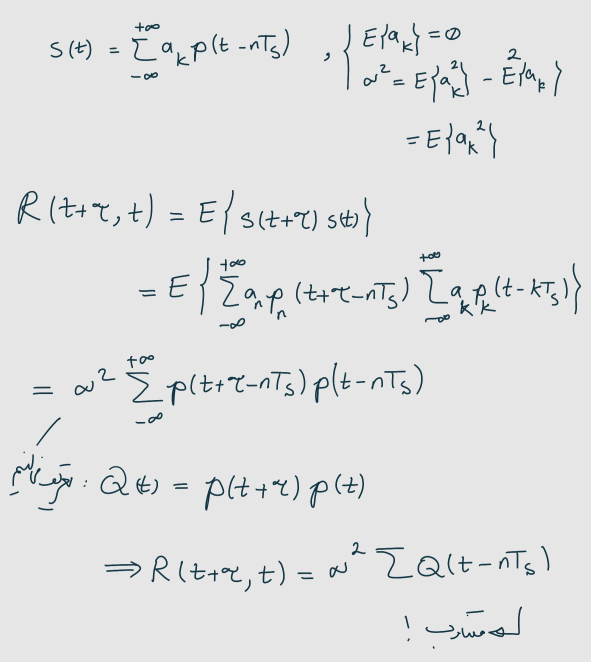

function [Y]=conv_m(x,h) 
m=length(x);
n=length(h);
X=[x,zeros(1,n)];
H=[h,zeros(1,m)];
for i=1:n+m-1
    Y(i)=0;
    for j=1:m
        if(i-j+1>0)
            Y(i)=Y(i)+X(j)*H(i-j+1);
        end
    end
end
% plot results
%figure;
%stem(Y, '-ro');
%ylabel('Y[n]'); xlabel('n'); grid on;
%title('Convolution of Two Signals without conv function');
end